## Liquid-liquid phase diagram from the van Laar model

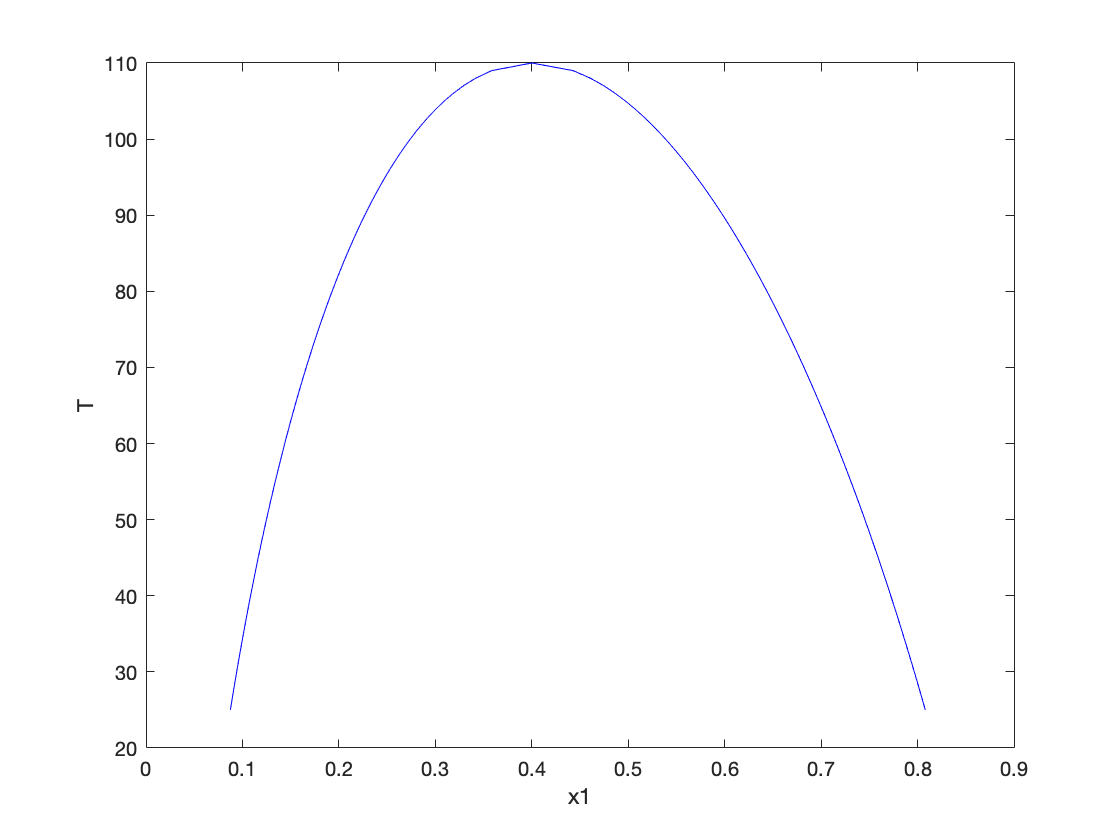

clear all; clc

Tc = 110;   % upper consolute temperature in centigrade
Tmin = 25;  % lowest temperature for the plot
xc = 0.4;   % upper consolute composition

% get van Laar coefficients
[a, b] = getAB(Tc, xc);

% make space to store the solution
npts = (Tc - Tmin);
xI = zeros(npts+1, 1);  % left curve, species 1 in phase 1
xII = zeros(npts+1, 1); % right curve, species 1 in phase 2
Temps = Tc:-1:Tmin;     % temperatures in centigrade

% put the consolute point into the output vectors
xI(1, 1) = xc;
xII(1, 1) = xc;
Temperature(1,1) = Tc;

% start a bit away from the consolute point
z = [xc - 0.05; xc + 0.05];
T = Tc - 1;     % starting point
tol = 1e-8;     % tolerance of Newton Raphson
for i = 1 : npts
    alpha = a / (T + 273.15);   % alpha parameter
    beta = b / (T + 273.15);
    % zero-order continuation method
    [z, success] = nonlinear_newton_raphson(z, tol, alpha, beta);
    % extract the results
    if success == 1
        xI(i+1, 1) = z(1);
        xII(i+1, 1) = z(2);
        Temperature(i+1, 1) = T;
    else
        warning('Newton Raphson failed.\n')
    end
    T = T - 1; % step down by 1 degree C for next iteration
end

plot (xI, Temperature, '-b')
hold on
plot (xII, Temperature, '-b')
hold off
xlabel('x1')
ylabel('T')

function [a, b] = getAB(Tc, x1)
% compute the van Laar coefficients
% from the upper consulute condition
Tc = Tc + 273.15; % convert Celsius to Kelvin
x2 = 1 - x1;
abfactor = (x1 * (1+x2)) / (x2 * (1+x1));
a = Tc * (x1 + x2 * abfactor)^3 / (2 * x1 * x2 * abfactor^2);
b = a * abfactor;
end

function out = vanLaar1(a, b, x)
% compues the activity coefficient for species 1
denom = 1 + a * x / (b * (1 - x));
denom2 = denom * denom;
out = exp(a / denom2);
end

function out = vanLaar2(a, b, x)
% compues the activity coefficient for species 2
denom = 1 + b * (1-x) / (a * x);
denom2 = denom * denom;
out = exp(b / denom2);
end

function R = getR(z, a, b)
R = zeros(2, 1);
x = z(1); y = z(2); % unpack the inputs
% compute the residuals for the equilibrium calculations
R(1) = x * vanLaar1(a, b, x) - y * vanLaar1(a, b, y);
R(2) = (1 - x) * vanLaar2(a, b, x) - (1 - y) * vanLaar2(a, b, y);
end

function J = getJ(z, a, b)
J = zeros(2, 2);
x = z(1); y = z(2); % unpack the inputs
J(1, 1) = vanLaar1(a, b, x) * (1 + x * Jterm1(a, b, x));
J(1, 2) = -vanLaar1(a, b, y) * (1 + y * Jterm1(a, b, y));
J(2, 1) = vanLaar2(a, b, x) * (-1 + (1-x) * Jterm2(a, b, x));
J(2, 2) = vanLaar2(a, b, y) * (1 - (1 - y) * Jterm2(a, b, y));
end

function out = Jterm1(a, b, x) 
% computes the extra term in J for species 1
denom = 1 + a * x / (b * (1 - x));
term1 = -2 * a * a / denom^3;
term2 = b * (1 - x)^2;
out = term1 / term2;
end

function out = Jterm2(a, b, x) 
% computes the extra term in J for species 2
denom = 1 + b * (1-x) / (a * x);
term1 = - 2 * b * b / denom^3;
term2 = - a * x^2;
out = term1 / term2;
end

function [x, success] = nonlinear_newton_raphson(x, tol, a, b)
% x = initial guess for x
% tol = criteria for convergence
% requires function R = getR(x)
% requires function J = getJ(x)
% flag = 0 if failed, 1 if converged
% a, b are parametes supplied for the LLe program
kmax = 100;         % max number of iterations allowed
R = getR(x, a, b);
k=0;                % counter
success = 1;

while norm(R) > tol
    J = getJ(x, a, b);  % compute Jacobian
    del = -J\R;         % Newton Raphson
    x = x + del;        % update x
    k = k + 1;          % update counter
    R = getR(x, a, b);% update R
    if k > kmax || max(x) == Inf || min(x) == -inf
        success = 0;
        warning('Did not converge.\n')
        break
    end
end
end

